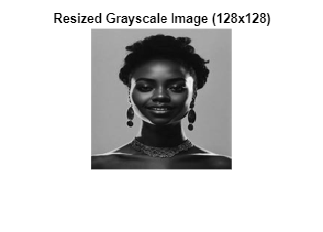

% pure rgb 2 grayscale for the Sobel Operator


clear; close all; clc;  % Add this at the top to close all figures and clear workspace

% Load the image
img = imread('queen4.jpg');  % Replace with your image file path

% Resize the image to 128x128
resized_img = imresize(img, [128, 128]);

% Convert the resized image to grayscale
gray_img = rgb2gray(resized_img);

% Display the grayscale image
imshow(gray_img);
title('Resized Grayscale Image (128x128)');


% Get the image size (height and width)
[height, width] = size(gray_img);

% Flatten the 2D grayscale image into a 1D vector (row-major order)
pixel_values = reshape(gray_img, 1, []);

% Print out the first few pixel values (for debugging)
disp('First few pixel values:');

First few pixel values:


disp(pixel_values(1:30));  % Show first 30 pixels

   170   167   169   166   168   168   168   168   167   167   167   166   165   165   165   165   165   165   165   164   164   164   164   165   165   164   163   163   163   163




% Save the 1D vector to a CSV file for feeding into Verilog
csvwrite('flattened_image1_128x128.csv', pixel_values);